# Notebook 02: Preprocessing and Feature Extraction

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 02**. Before running this notebook, you should have run Notebook 01 to get an understanding of the data you will be working with.

## Instructions

- Run each cell in order.

- Modify the lines that have green comments.

- This notebook, by default, assumes that time/samples are rows and channels are columns.

- Feel free to try more involved preprocessing steps, but assign your results back to the appropriate variables.

## Preprocessing

### Step 1: Load the dataset

clearvars
load('/Users/rebeccamoore/Desktop/PhD/Neuro Robotics/ResearchProject2/datasets/training_dataset.mat')

### Step 2: Visualize the raw data

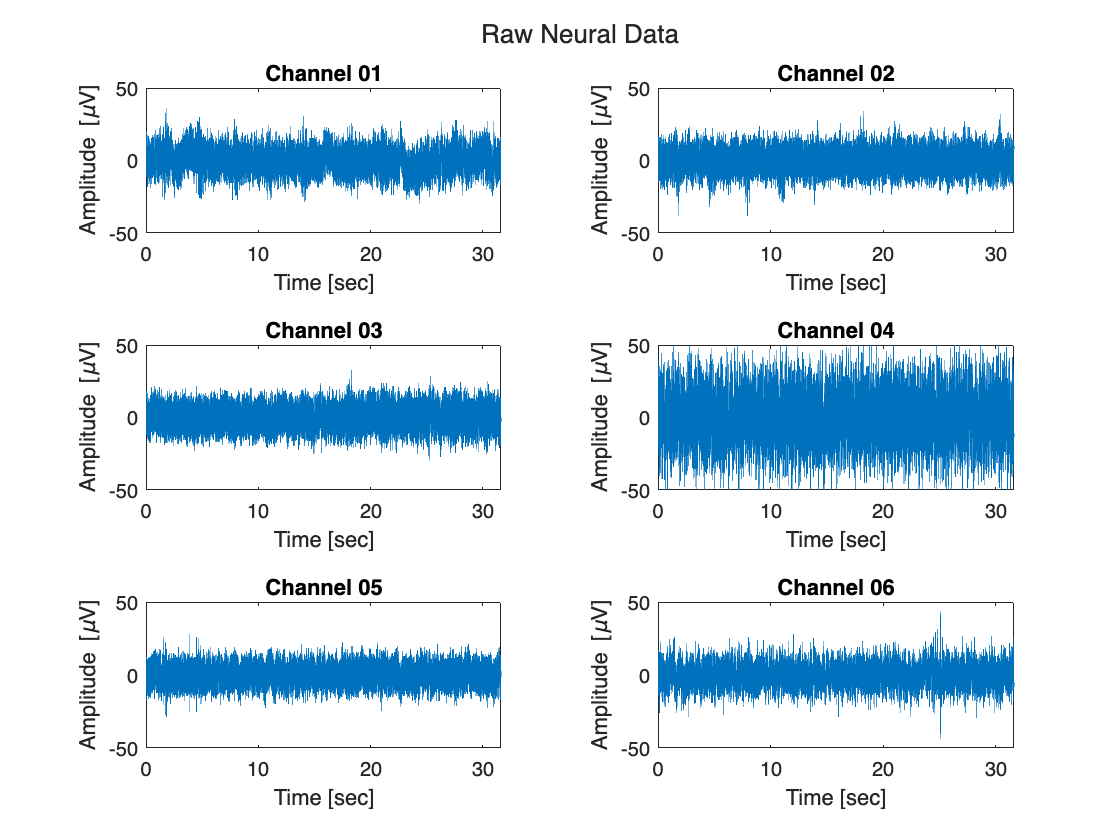

fig_1 = plot_raw_data(training_data);

### Step 3: Filter the data

#### A. Provide information for designing the filter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 500; % Change this random value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut-off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed.

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = filter(b, a, training_data.raw_neural_data, ch_init_conds);

#### Step 4: Visualize the filtered data

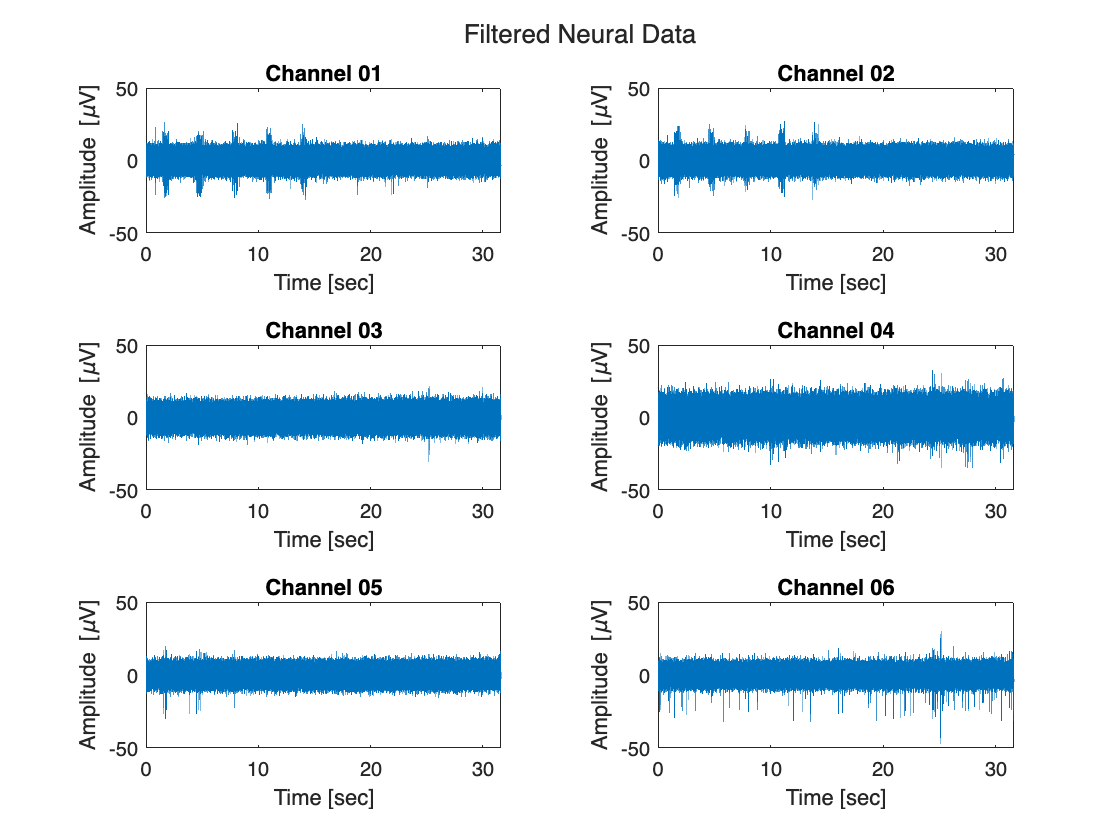

fig_2 = plot_filt_data(filt_neural_data, sample_rate);

## Spike Detection

If your signal processing steps worked well, you should be able to detect some action action potentials.

### Step 1: Find the locations of the spikes (action potentials) in all channels

Your goal for this step is to provide the locations of spike occurrences in the `filt_neural_data` matrix.

You will start with the array `spike_locations`, which has the same shape as `filt_neural_data` and whose entries have been initialized to zero.

spike_locations = zeros(size(filt_neural_data))

spike_locations =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Then, modify the code below to replace `0`s with `1`s whenever you find a spike. We do this to leverage MATLAB's [logical indexing](https://blogs.mathworks.com/loren/2013/02/20/logical-indexing-multiple-conditions/) functionality down the line.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
STD = std(filt_neural_data)

STD = 1×6 single row vector
    3.5750    3.6387    4.0373    5.6135    3.4355    3.2090


ts = 4 * STD

ts = 1×6 single row vector
   14.3000   14.5549   16.1492   22.4541   13.7421   12.8358


spike_locations = (filt_neural_data > ts); % This code generates random spike locations. Replace with a spike detection algorithm

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% Diff function for spike detection 
% calculate something based on spike location, don't just feed those right in

spike_locations

spike_locations = 948199×6 logical array
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0


### Step 2: Visualize the spike locations as spike trains in a raster plot

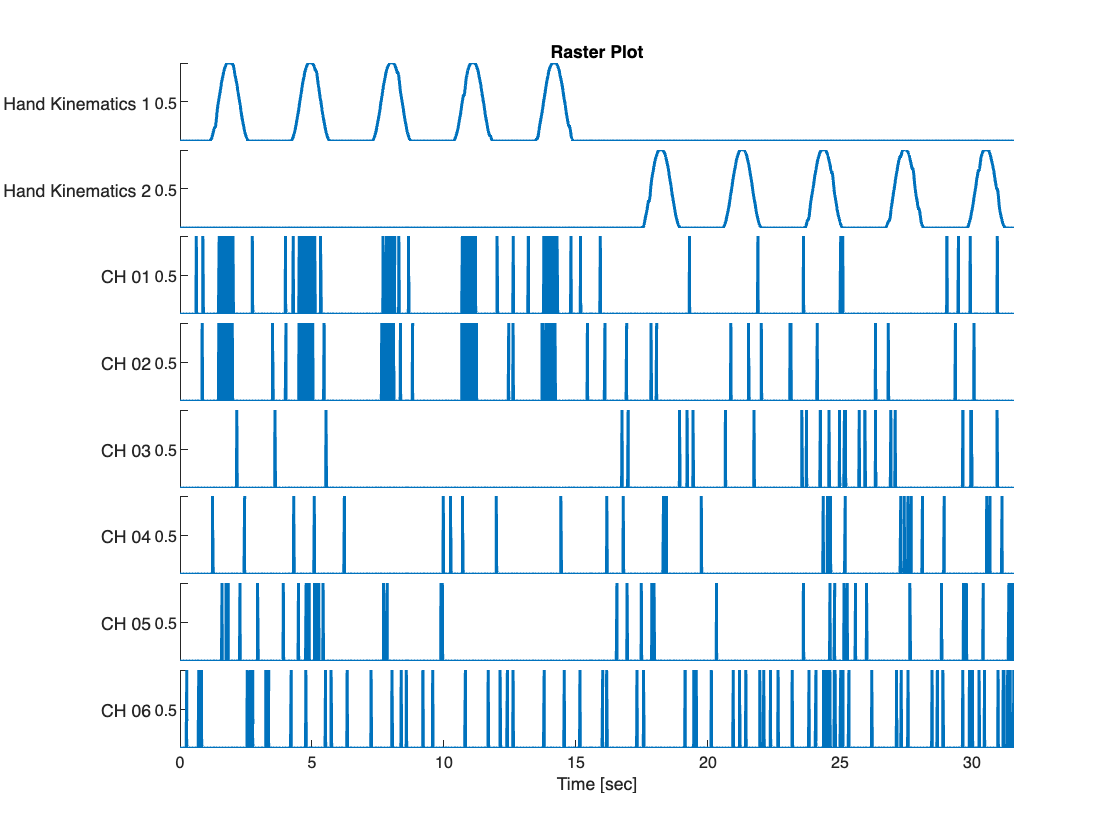

fig_3 = plot_spike_trains(spike_locations, training_data);

### Step 3: Plot the action potential waveforms using the spike locations

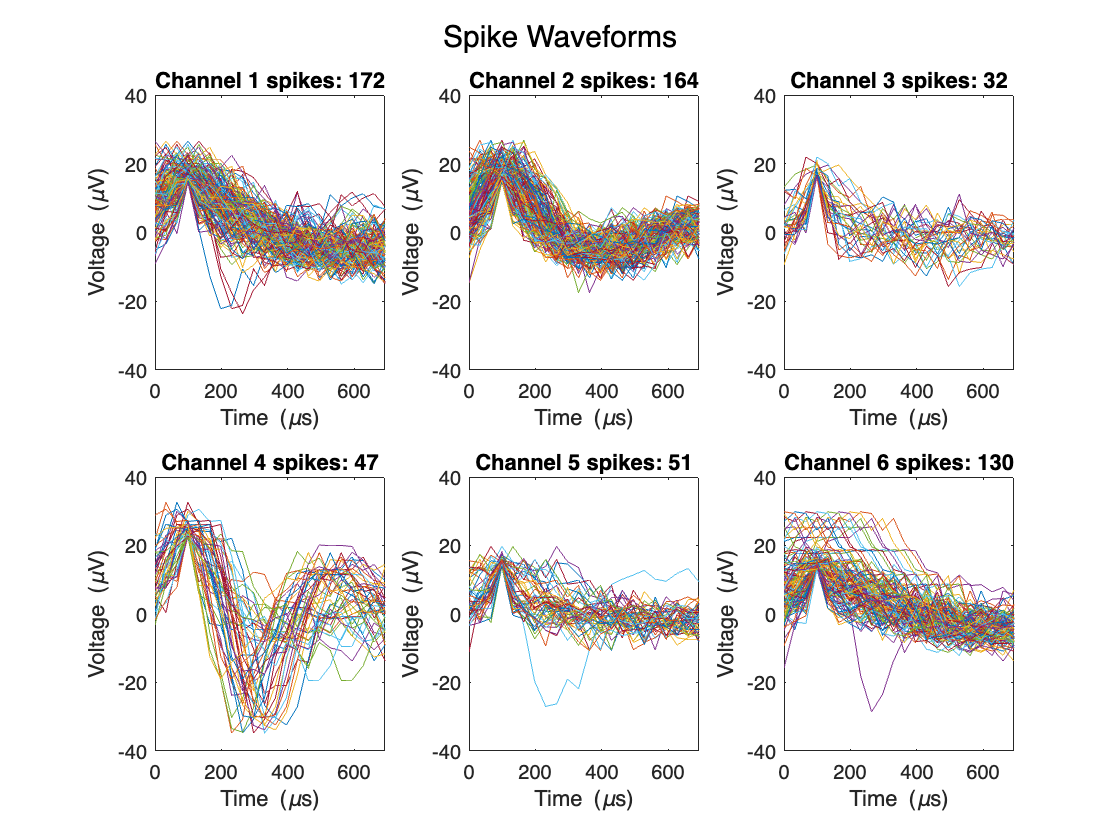

spike_waveforms = get_action_potentials(spike_locations, filt_neural_data, 'Spike Waveforms');

### Step 4: Calculate the SNR of each detected spike

First, let's explore how we have stored the waveforms associated with each spike. 

`spike_waveforms` is a [MATLAB cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) that has one row per channel.

spike_waveforms

spike_waveforms = 6×1 cell array
    {1×172 cell}
    {1×164 cell}
    {1×32  cell}
    {1×47  cell}
    {1×51  cell}
    {1×130 cell}


Each one of those rows is also a cell array containing a variable number of waveforms based on the information in `spike_locations`. In order to access the waveforms, you need to specify the channel you want, and then the waveform you are interested in. The waveform itself is a vector containing `22` samples of neural data (`0.1 ms` before and `0.6 ms `after the spike detection).

chan_idx = 1; % random channel
spike_waveforms{chan_idx}

ans = 1×172 cell array
    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×

waveform_idx = 7; % random waveform
waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data = 22×1 single column vector
   12.4491
   12.9104
   17.5340
   15.5416
   15.5159
   20.2144
   14.7859
    5.7067
    2.3988
   -0.1357


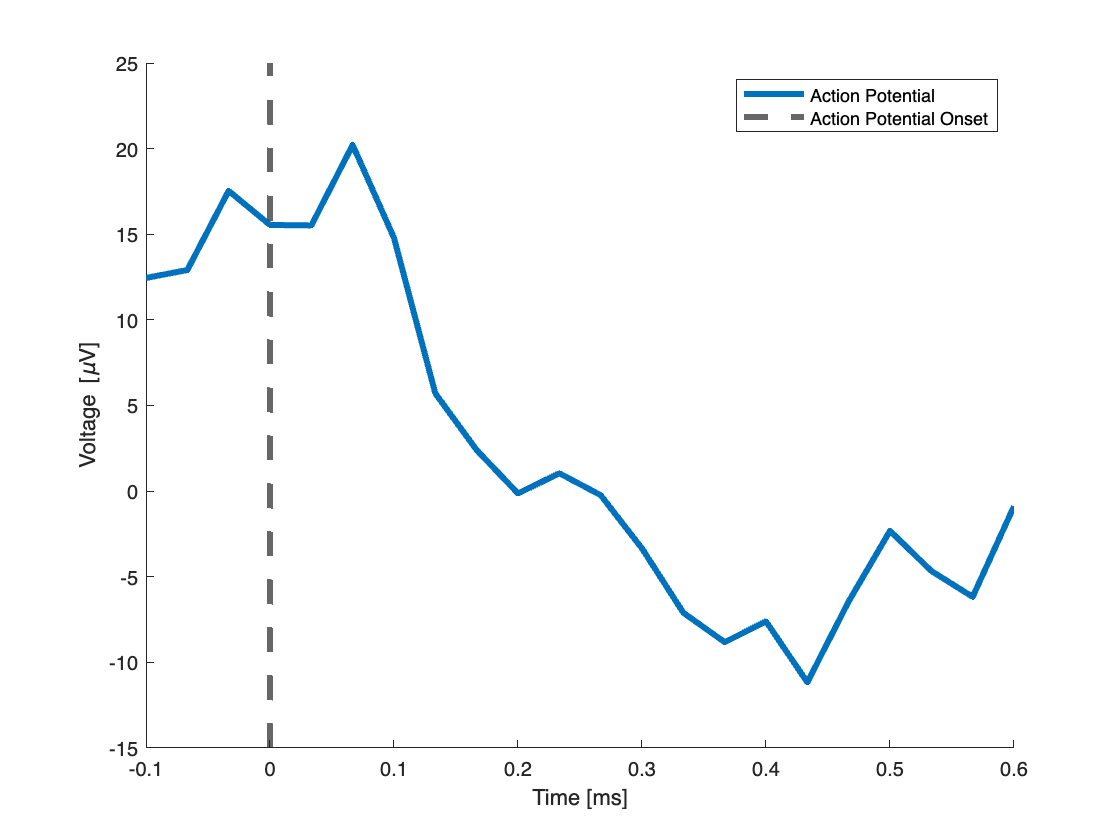

figure
waveform_time = (-3:1:18)'/training_data.sample_rate*1e3;
plot(waveform_time, waveform_data, LineWidth=3)
xline(0, LineWidth=3, LineStyle="--")
xlabel("Time [ms]")
ylabel("Voltage [\muV]")
legend(["Action Potential", "Action Potential Onset"])
box off

Now, consider the image below, which shows action potentials as a function of distance to a neuron. Which action potential has the best SNR in the image below? Which channel of data provides the best SNR? Where might each channel be in relation to a given neuron? Are any channels recording from multiple neurons? 

One of your requirements for this research project is to determine if there are any statistical differences in the SNR among the electrodes.

For more context about the image below, read the document titled *"Introduction to Neural Recordings"* under the Neural Recordings Reading Assignment on Canvas. 

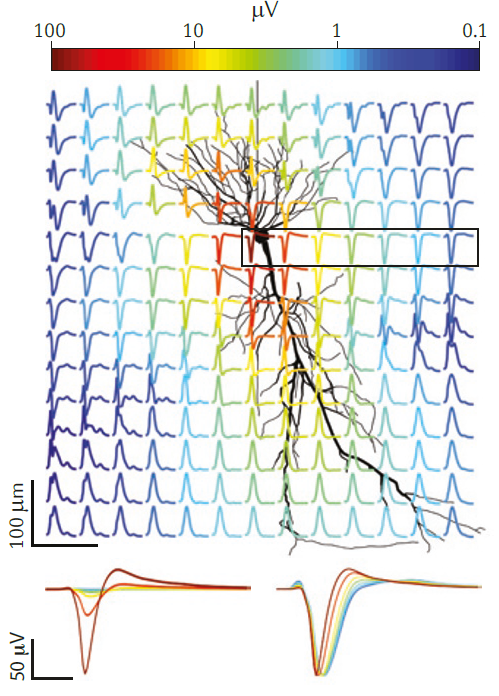

Calculate the SNR of each waveform in `spike_waveforms`. Use the following code to access each waveform:

for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};
        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%
        avg = mean(waveform_data)

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end

avg = single
1.0070

avg = single
3.6387

avg = single
2.9790

avg = single
2.1678

avg = single
1.5353

avg = single
3.1891

avg = single
2.6913

avg = single
1.7505

avg = single
0.7713

avg = single
-0.1828

avg = single
3.9588

avg = single
3.5249

avg = single
2.8896

avg = single
4.5101

avg = single
3.9224

avg = single
3.3933

avg = single
2.5962

avg = single
1.1640

avg = single
4.3198

avg = single
3.8317

avg = single
1.6463

avg = single
0.8767

avg = single
4.2905

avg = single
3.5526

avg = single
2.7138

avg = single
2.6112

avg = single
2.1403

avg = single
1.6612

avg = single
1.3510

avg = single
0.5295

avg = single
-0.0697

avg = single
3.4385

avg = single
3.3177

avg = single
2.4716

avg = single
3.4268

avg = single
2.3510

avg = single
0.8240

avg = single
3.2570

avg = single
2.4757

avg = single
4.1447

avg = single
3.6400

avg = single
3.2240

avg = single
1.8044

avg = single
1.2782

avg = single
0.9619

avg = single
2.9647

avg = single
2.1047

avg = single
1.4051

avg = single
1.2390

avg = single
1.1800

avg = single
3.4606

avg = single
2.0841

avg = single
0.3951

avg = single
3.4178

avg = single
1.3745

avg = single
6.1724

avg = single
3.8981

avg = single
2.9666

avg = single
1.4084

avg = single
3.6209

avg = single
3.2843

avg = single
4.9752

avg = single
1.6242

avg = single
0.3709

avg = single
3.9149

avg = single
3.4594

avg = single
2.9769

avg = single
2.1212

avg = single
4.6045

avg = single
3.2104

avg = single
2.4448

avg = single
-0.2257

avg = single
0.2662

avg = single
1.1184

avg = single
2.0590

avg = single
1.3611

avg = single
0.4307

avg = single
2.4648

avg = single
1.8685

avg = single
5.1749

avg = single
3.2264

avg = single
3.0355

avg = single
2.4767

avg = single
3.8566

avg = single
3.0455

avg = single
2.1987

avg = single
1.5005

avg = single
2.4184

avg = single
4.1946

avg = single
3.8177

avg = single
3.3187

avg = single
2.5519

avg = single
1.5256

avg = single
1.7550

avg = single
0.8867

avg = single
3.6977

avg = single
3.0939

avg = single
2.2539

avg = single
3.4091

avg = single
2.4649

avg = single
0.4974

avg = single
3.9255

avg = single
3.4616

avg = single
2.9739

avg = single
2.3145

avg = single
2.6104

avg = single
2.3193

avg = single
2.9005

avg = single
2.3361

avg = single
1.8410

avg = single
2.1953

avg = single
5.8634

avg = single
5.6613

avg = single
4.2570

avg = single
3.2617

avg = single
2.2492

avg = single
2.4721

avg = single
4.5521

avg = single
1.0642

avg = single
0.1505

avg = single
3.4238

avg = single
2.9334

avg = single
2.6465

avg = single
2.0082

avg = single
0.8469

avg = single
-0.2253

avg = single
3.7529

avg = single
3.1217

avg = single
2.3403

avg = single
0.4401

avg = single
0.5874

avg = single
1.8979

avg = single
2.0260

avg = single
1.2370

avg = single
2.4311

avg = single
5.4242

avg = single
5.0233

avg = single
4.0888

avg = single
3.4973

avg = single
2.3202

avg = single
1.1463

avg = single
0.2220

avg = single
-1.2636

avg = single
3.1488

avg = single
2.2626

avg = single
1.4664

avg = single
-0.4788

avg = single
3.0582

avg = single
2.6212

avg = single
1.2261

avg = single
5.0683

avg = single
4.1978

avg = single
3.2380

avg = single
1.8743

avg = single
1.1283

avg = single
4.1668

avg = single
3.1081

avg = single
3.4251

avg = single
2.8651

avg = single
1.5445

avg = single
-0.0736

avg = single
2.2396

avg = single
1.1403

avg = single
0.9607

avg = single
3.3429

avg = single
0.8538

avg = single
0.5767

avg = single
1.1544

avg = single
0.6899

avg = single
1.3676

avg = single
2.0347

avg = single
-0.1362

avg = single
1.3563

avg = single
1.3231

avg = single
3.1049

avg = single
3.3095

avg = single
3.3996

avg = single
0.1702

avg = single
2.7125

avg = single
2.6646

avg = single
2.0281

avg = single
1.9861

avg = single
1.9838

avg = single
2.4322

avg = single
2.3132

avg = single
3.0434

avg = single
3.3195

avg = single
2.8953

avg = single
3.1313

avg = single
2.8556

avg = single
3.3988

avg = single
3.5303

avg = single
3.3884

avg = single
3.0122

avg = single
2.5583

avg = single
2.2737

avg = single
2.9008

avg = single
3.1550

avg = single
2.9897

avg = single
2.2740

avg = single
2.8995

avg = single
2.9461

avg = single
2.8916

avg = single
2.7164

avg = single
2.6496

avg = single
1.7567

avg = single
1.3498

avg = single
2.4375

avg = single
2.7465

avg = single
2.9435

avg = single
3.4575

avg = single
4.1459

avg = single
4.3790

avg = single
3.1144

avg = single
3.3278

avg = single
3.3753

avg = single
3.5731

avg = single
3.3079

avg = single
3.4372

avg = single
3.2434

avg = single
2.8595

avg = single
2.4569

avg = single
2.7414

avg = single
2.9248

avg = single
2.8723

avg = single
2.5579

avg = single
1.9163

avg = single
2.1413

avg = single
1.7808

avg = single
4.0360

avg = single
4.4762

avg = single
4.4406

avg = single
4.3591

avg = single
0.5606

avg = single
2.0774

avg = single
2.5164

avg = single
2.0825

avg = single
0.1720

avg = single
2.5917

avg = single
2.8371

avg = single
2.0831

avg = single
2.3127

avg = single
2.5734

avg = single
2.2366

avg = single
3.5011

avg = single
3.7380

avg = single
3.8310

avg = single
3.4734

avg = single
3.4904

avg = single
3.4685

avg = single
3.1699

avg = single
3.5985

avg = single
3.8576

avg = single
3.6797

avg = single
1.8947

avg = single
1.7884

avg = single
1.5689

avg = single
1.1304

avg = single
0.2986

avg = single
0.7907

avg = single
2.9985

avg = single
2.9850

avg = single
3.1765

avg = single
2.2951

avg = single
2.2985

avg = single
2.2521

avg = single
1.9452

avg = single
1.9951

avg = single
1.9047

avg = single
2.5661

avg = single
2.6525

avg = single
2.6524

avg = single
2.3103

avg = single
0.8664

avg = single
0.7419

avg = single
0.7018

avg = single
2.8154

avg = single
2.5724

avg = single
2.6701

avg = single
3.4793

avg = single
3.8211

avg = single
3.7486

avg = single
3.4422

avg = single
3.6618

avg = single
3.8207

avg = single
3.7188

avg = single
3.3715

avg = single
2.6698

avg = single
4.9533

avg = single
4.8203

avg = single
4.7212

avg = single
4.0726

avg = single
3.3212

avg = single
-0.3005

avg = single
0.3281

avg = single
1.1377

avg = single
2.9070

avg = single
3.3984

avg = single
3.8015

avg = single
3.8275

avg = single
4.2605

avg = single
4.4250

avg = single
4.5540

avg = single
4.0244

avg = single
2.4002

avg = single
2.2518

avg = single
1.1622

avg = single
3.5437

avg = single
3.5717

avg = single
3.6082

avg = single
3.2028

avg = single
2.2160

avg = single
2.2257

avg = single
2.1767

avg = single
2.0507

avg = single
2.0129

avg = single
2.1158

avg = single
2.2111

avg = single
2.5952

avg = single
3.0600

avg = single
2.5981

avg = single
-0.1720

avg = single
1.1290

avg = single
1.6854

avg = single
2.4027

avg = single
0.1849

avg = single
1.2008

avg = single
0.0204

avg = single
-0.6419

avg = single
1.1438

avg = single
2.5671

avg = single
0.5052

avg = single
1.5527

avg = single
1.2000

avg = single
1.9986

avg = single
0.7776

avg = single
1.5106

avg = single
0.6715

avg = single
1.8595

avg = single
1.9515

avg = single
0.9916

avg = single
1.6918

avg = single
1.3005

avg = single
0.6489

avg = single
1.7412

avg = single
0.8963

avg = single
2.7050

avg = single
-0.2454

avg = single
-0.2639

avg = single
1.6667

avg = single
2.3982

avg = single
2.3886

avg = single
4.5466

avg = single
4.3053

avg = single
3.8562

avg = single
2.3993

avg = single
2.2348

avg = single
-0.4473

avg = single
-0.9175

avg = single
1.9583

avg = single
1.4512

avg = single
1.2027

avg = single
1.6782

avg = single
0.4154

avg = single
2.2738

avg = single
0.2453

avg = single
1.1901

avg = single
2.0589

avg = single
0.6181

avg = single
3.6416

avg = single
3.3666

avg = single
2.6153

avg = single
2.2050

avg = single
1.1966

avg = single
0.3320

avg = single
3.9805

avg = single
4.2247

avg = single
4.2337

avg = single
6.0143

avg = single
2.7371

avg = single
2.3046

avg = single
2.1554

avg = single
1.5004

avg = single
7.1090

avg = single
1.8892

avg = single
1.9347

avg = single
4.5349

avg = single
2.4301

avg = single
6.6664

avg = single
6.2012

avg = single
5.1831

avg = single
5.5452

avg = single
5.6229

avg = single
1.1829

avg = single
6.1789

avg = single
6.1981

avg = single
5.9452

avg = single
5.1576

avg = single
3.0870

avg = single
3.3020

avg = single
1.5542

avg = single
3.1738

avg = single
3.4297

avg = single
2.8871

avg = single
1.1953

avg = single
1.8936

avg = single
2.2023

avg = single
3.3218

avg = single
1.3009

avg = single
7.2981

avg = single
7.0066

avg = single
6.2580

avg = single
5.4262

avg = single
5.7345

avg = single
4.3997

avg = single
2.8959

avg = single
2.3516

avg = single
1.5229

avg = single
5.2954

avg = single
2.9522

avg = single
2.4906

avg = single
1.7379

avg = single
4.8847

avg = single
2.2506

avg = single
1.8866

avg = single
1.1915

avg = single
-1.0041

avg = single
0.3607

avg = single
5.5076

avg = single
5.8998

avg = single
4.6939

avg = single
2.6233

avg = single
3.8341

avg = single
3.2013

avg = single
4.2190

avg = single
0.4343

avg = single
1.0202

avg = single
1.7274

avg = single
0.2694

avg = single
1.2748

avg = single
5.1233

avg = single
4.8740

avg = single
2.9836

avg = single
0.6576

avg = single
0.1517

avg = single
1.4626

avg = single
1.2959

avg = single
-1.0266

avg = single
-0.3343

avg = single
1.7665

avg = single
0.3912

avg = single
1.7258

avg = single
0.0011

avg = single
0.6354

avg = single
1.2580

avg = single
0.3517

avg = single
2.3669

avg = single
1.3313

avg = single
3.8702

avg = single
1.7658

avg = single
1.8437

avg = single
1.7899

avg = single
0.8254

avg = single
1.0938

avg = single
0.0222

avg = single
0.0863

avg = single
2.3633

avg = single
0.8311

avg = single
1.7778

avg = single
0.6691

avg = single
1.8706

avg = single
0.3534

avg = single
3.1769

avg = single
2.9878

avg = single
2.2959

avg = single
3.7328

avg = single
0.9083

avg = single
1.9866

avg = single
3.6154

avg = single
0.4189

avg = single
1.9566

avg = single
3.4979

avg = single
1.5527

avg = single
0.0680

avg = single
0.0908

avg = single
0.2186

avg = single
2.0861

avg = single
0.0101

avg = single
2.8976

avg = single
0.8402

avg = single
0.2388

avg = single
2.8915

avg = single
2.7599

avg = single
2.5588

avg = single
2.2131

avg = single
1.9138

avg = single
3.6240

avg = single
3.1093

avg = single
1.7194

avg = single
0.9045

avg = single
1.9771

avg = single
3.2202

avg = single
1.8278

avg = single
1.0678

avg = single
-0.8466

avg = single
2.0784

avg = single
1.6988

avg = single
2.8777

avg = single
3.8973

avg = single
2.0120

avg = single
3.3665

avg = single
2.4434

avg = single
3.6004

avg = single
3.8199

avg = single
2.9807

avg = single
0.1213

avg = single
2.1449

avg = single
5.2780

avg = single
3.8813

avg = single
3.0570

avg = single
3.3767

avg = single
2.0704

avg = single
4.4636

avg = single
4.3304

avg = single
3.4635

avg = single
2.0615

avg = single
6.2828

avg = single
6.2194

avg = single
5.9672

avg = single
5.6120

avg = single
3.5114

avg = single
0.7181

avg = single
0.3461

avg = single
4.4926

avg = single
4.2904

avg = single
3.6807

avg = single
2.9669

avg = single
2.1067

avg = single
2.6026

avg = single
11.2114

avg = single
11.5610

avg = single
11.3465

avg = single
10.3920

avg = single
9.4404

avg = single
8.2256

avg = single
6.8530

avg = single
5.5195

avg = single
3.9898

avg = single
2.4416

avg = single
1.1528

avg = single
-0.9271

avg = single
11.8673

avg = single
12.0063

avg = single
11.7801

avg = single
11.2999

avg = single
10.0642

avg = single
8.5988

avg = single
6.8979

avg = single
5.2155

avg = single
3.2326

avg = single
1.4838

avg = single
3.4490

avg = single
1.4387

avg = single
1.1288

avg = single
3.9320

avg = single
2.6500

avg = single
3.2773

avg = single
2.6421

avg = single
2.0317

avg = single
3.8243

avg = single
3.2071

avg = single
-0.0540

avg = single
3.3793

avg = single
3.3079

avg = single
2.7173

avg = single
2.0580

avg = single
1.2699

avg = single
1.7357

avg = single
3.3080

avg = single
2.8610

avg = single
2.5852

avg = single
2.6914

avg = single
0.4966

avg = single
-0.0677

avg = single
1.7615

avg = single
0.7057

avg = single
4.4466

avg = single
3.7412

avg = single
0.7051

avg = single
3.9338

avg = single
3.3418

avg = single
2.9058

avg = single
1.9940

avg = single
0.2647

avg = single
3.4554

avg = single
3.0592

After you've calculated SNRs, make sure to **plot the SNR values** and **run stats**!

## Feature Extraction

The only requirement for generating features is that the length of your `neural_features` must match the size of the kinematics. The reason for this is that the kinematics are acting as labels for your features. For more information about this requirement, check notebook 03 on training the neural network.

If the lengths don't match as a result of your calculations, you can [pad the array with zeros](https://www.mathworks.com/help/images/ref/padarray.html).

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
neural_features = training_data.hand_kinematics; % nonsensical code that passes the assertion below
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

figure
hold on
plot(training_data.hand_kinematics(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(training_data.hand_kinematics(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(normalize(neural_features, "range", [0 1]),'Color',"#000000" ,'LineWidth', 1.5)
hold off
box off
xlabel("Samples")
ylabel("Amplitude")
legend(["Joint 1 Position", "Joint 2 Position", "Features"])
save("results\features", "neural_features")

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. You do not need to change or understand the code below, but you are welcome to do so if it helps with your project.

function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.DisplayLabels = ["Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan) ' spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end